N = 10000;
Fs = 1000;
frequencies = Fs * (0:N/2) / N;

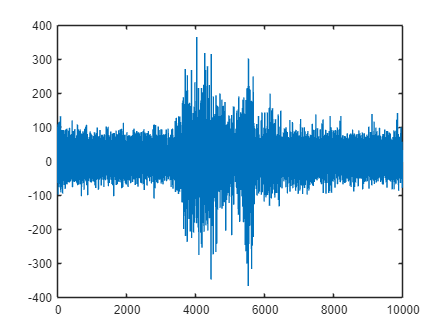

emg_values = readmatrix("emg_data.csv");
sensor_1 = emg_values(:,1);
plot(sensor_1)
xlim([0 length(sensor_1)])

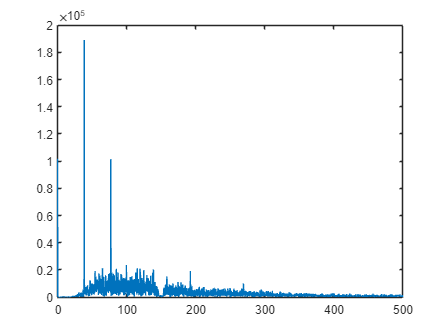

X = fft(sensor_1);
emg_1_fft_mag = abs(X(1:N/2 + 1));
plot(frequencies, emg_1_fft_mag)
xlim([min(frequencies), max(frequencies)]);

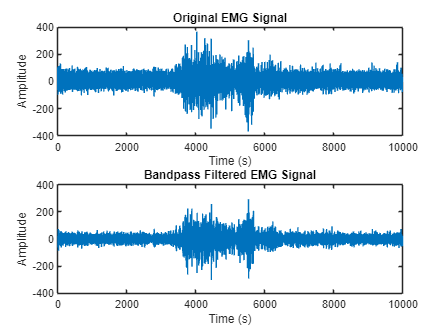

order = 4;                 % Filter order
Fc_l = 50;    % Cutoff frequency in Hz
Fc_h = 150;    % Cutoff frequency in Hz

[b, a] = butter(order, [Fc_l, Fc_h] / (Fs/2), 'bandpass');

% Generate a sample EMG signal (replace this with your actual data)

% Apply the high-pass filter
filtered_emg = filter(b, a, sensor_1);

% Plot the original and filtered signals
figure;
subplot(2,1,1);
plot(sensor_1);
title('Original EMG Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2,1,2);
plot(filtered_emg);
title('Bandpass Filtered EMG Signal');
xlabel('Time (s)');
ylabel('Amplitude');

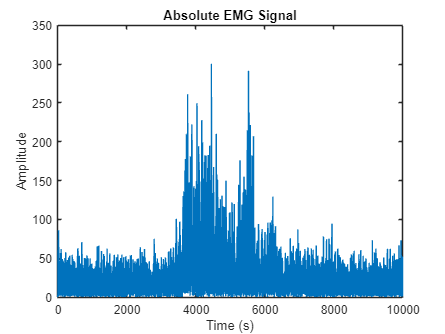

figure;
plot(abs(filtered_emg));
title('Absolute EMG Signal');
xlabel('Time (s)');
ylabel('Amplitude');

mav = mean(abs(filtered_emg))

mav = 30.9234

% Display or use the MAV value
disp(['Mean Absolute Value (MAV): ', num2str(mav)]);

Mean Absolute Value (MAV): 30.9234


RMS = sqrt(mean(pow2(abs(filtered_emg))))

RMS = 1.6134e+43

% Display or use the MAV value
disp(['Root Mean Square (RMS): ', num2str(RMS)]);

Root Mean Square (RMS): 1.613416742933092e+43


WL = 0;

for i = 1:N-1
    WL = WL + abs(filtered_emg(i + 1) - filtered_emg(i));
end
disp(['Waveform Length (WL): ', num2str(RMS)]);

Waveform Length (WL): 1.613416742933092e+43


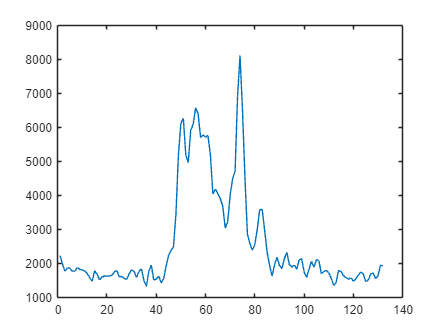

window_length = 0.150 * Fs;  % 150 ms window length
overlap = window_length / 2; % 50% overlap

% Calculate Waveform Length with sliding windows
wl_values = [];
for i = 1:overlap:length(filtered_emg)-window_length
    segment = filtered_emg(i:i+window_length-1);
    wl = sum(abs(diff(segment)));
    wl_values = [wl_values, wl];
end

plot(wl_values)

% Display or use the Waveform Length values
%disp(['Waveform Length values: ', num2str(wl_values)]);